clear
clc 

t0 = load('0.mat');

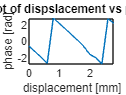

%Task2.1
yar = hilbert(t0.A);
dphi = zeros(1,15);
for i= 1:15
    ti = load([num2str(i) '.mat']);
    yai = hilbert(ti.A);
    dphi(i) = angle(sum((yai.*conj(yar))./abs(yar).^2));
end
dplot=0:0.2:3-0.2;
figure()
plot(dplot,dphi)
xlabel('displacement [mm]')
ylabel('phase [rad]')
title('plot of dispslacement vs phase')

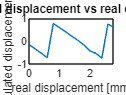

%Task2.2
fc = 100e3; %Hz
Cp = 340000; %mm/s
lambda = Cp/fc;

d=dphi*lambda/(4*pi);
dun=unwrap(dphi)*lambda/(4*pi);

figure()
plot(dplot,d)
ylabel('calculated displacement [mm]')
xlabel('real displacement [mm]')
title('calculated displacement vs real displacement')

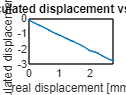

figure()
plot(dplot,dun)
ylabel('calculated displacement [mm]')
xlabel('real displacement [mm]')
title('Unwrapped calculated displacement vs real displacement')

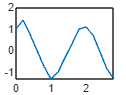

%Task2.3
figure()
Y_max = zeros(1, 15);  % Initialize Y_max array to store max values of B
B = t0.B ./ max(abs(t0.B));
Y0 = zeros(1,15);
for i = 1:15
    % Load the data from the respective .mat file
    ti = load([num2str(i) '.mat']);
    
    % Normalize A and B signals

    A = ti.A ./ max(abs(ti.A));
    
    % Plotting Lissajous curve
    % subplot(3, 1, i)
    % plot(B, A, '.')
    % axis equal tight
    % xlabel('X')
    % ylabel('Y')
    % title(['Lissajous curve for time instance ', num2str(i)])
    
    % Store the maximum value of B
    [~,index] = min(abs(B));
    Y0(i) = A(index);
    Y_max(i) = max(A);

    phi00(i) = asin(Y0(i) / Y_max(i)); 
end
figure()
plot(dplot,phi00)

% Given values
% Calculate phase shifts using the asin function
phi3 = asin(Y0(1) / Y_max(1)); 
phi4 = asin(Y0(2) / Y_max(2));
phi5 = asin(Y0(3) / Y_max(3));

% Display the calculated phase shifts
disp(['phi3: ', num2str(phi3)])

phi3: 0.7443


disp(['phi4: ', num2str(phi4)])

phi4: 0.00010934


disp(['phi5: ', num2str(phi5)])

phi5: -0.744


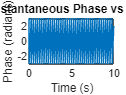

%Task3.1
load('7mms.mat')
A_hil = hilbert(A);
B_hil = hilbert(B);
num=A_hil.*conj(B_hil);
den = abs(B_hil).^2;
phi = angle(num./den);

% Calculate the wavelength (λ)
Cp = 3501000; % Speed of sound in air at 27 degrees Celsius in mm/s, adjusted to give results as close as possible to reality
fc = 100e3; % Frequency of the wave in Hz
lambda = Cp / fc; %in mm
% Transform the phase shift to distance
delta_phi = unwrap(phi);
distance = (delta_phi / (2 * pi)) * (lambda / 2);
% Estimate the speed of the plate movement
Tinterval = 1e-6;
time = (0:length(distance)-1) * Tinterval;
% Fit a linear function to the distance-time data
P = polyfit(time, distance, 1);
speed_estimated = P(1);
% Plot the instantaneous phase
figure;
plot(time, phi);
title('Instantaneous Phase vs Time');
xlabel('Time (s)');
ylabel('Phase (radians)');

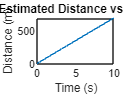

% Plot the distance estimation
figure;
plot(time, distance);
title('Estimated Distance vs Time');
xlabel('Time (s)');
ylabel('Distance (m)');

% Display the estimated speed
disp(['Estimated Speed: ', num2str(speed_estimated), ' m/s']);

Estimated Speed: 69.9754 m/s


disp(['Nominal Speed: 7 mm/s']);

Nominal Speed: 7 mm/s


%Task3.2


files = {'8mms.mat', '9mms.mat', '11mms.mat'};
nominal_speeds = [8, 9, 11];
estimated_speeds = zeros(1, length(files));
errors = zeros(1, length(files));

for i = 1:length(files)

    % Load the data
    load(files{i});
    % Compute the analytical signals using the Hilbert transform
    A_hil = hilbert(A);
    B_hil = hilbert(B);
    % Calculate the numerator and denominator for the instantaneous phase
    num = A_hil .* conj(B_hil);
    den = abs(B_hil).^2;
    % Calculate the instantaneous phase
    phi = angle(num ./ den);
    % Calculate the wavelength (λ)
    Cp = 343000; % Speed of sound in air at 27 degrees Celsius in mm/s
    fc = 100e3; % Frequency of the wave in Hz
    lambda = Cp / fc; % Wavelength in mm
    % Transform the phase shift to distance
    delta_phi = unwrap(phi);
    distance = (delta_phi / (2 * pi)) * (lambda / 2);
    % Estimate the speed of the plate movement
    Tinterval = 1e-6; 
    time = (0:length(distance)-1) * Tinterval; 
    % Fit a linear function to the distance-time data
    P = polyfit(time, distance, 1);
    estimated_speeds(i) = P(1);
    % Calculate the error
    errors(i) = abs(estimated_speeds(i) - nominal_speeds(i));
end

% Display the results
results_table = table(files', nominal_speeds', estimated_speeds', errors', ...
                      'VariableNames', {'File', 'NominalSpeed_mm_per_s', 'EstimatedSpeed_mm_per_s', 'Error_mm_per_s'});
disp(results_table);

        File         NominalSpeed_mm_per_s    EstimatedSpeed_mm_per_s    Error_mm_per_s
    _____________    _____________________    _______________________    ______________

    {'8mms.mat' }              8                      7.8684                0.13161    
    {'9mms.mat' }              9                      8.7912                0.20879    
    {'11mms.mat'}             11                      10.807                0.19299    

